%% 2.17
clearvars;
clc;
x = sym('x', 'real');
k = sym('k', 'real');
syms A B C D
 
%% 1)
f1 = A*exp(1i*k*x) + B*exp(-1i*k*x);
Cval = A + B

$$Cval = A+B$$

Dval = 1i*(A - B)

$$Dval = A\,\mathrm{i}-B\,\mathrm{i}$$

 
%% 2)
f2 = C*cos(k*x) + D*sin(k*x);
Aval = (C - 1i*D)/2

$$Aval = \frac{C}{2}-\frac{\text{D}\,\mathrm{i}}{2}$$

Bval = (C + 1i*D)/2

$$Bval = \frac{C}{2}+\frac{\text{D}\,\mathrm{i}}{2}$$

 
%%2.21
clearvars;
clc;
m=sym('m','positive');
hbar = sym('hbar', 'positive');
t=sym('t','positive');
pi=sym('pi','positive');
A = sym('A', 'positive');
a= sym('a', 'positive');
x = sym('x', 'real');
k = sym('k', 'real');
gamma = sym('gamma', 'positive');
sympref('FourierParameters',[1/sqrt(2*pi) -1]);
 
%% a)
psi(x) = A*exp(-a*x^2);
Anorm = solve(int(psi(x)^2,x,-inf,inf)==1,A)

$$Anorm = \frac{2^{1/4}\,a^{1/4}}{\pi^{1/4}}$$

psinorm(x) = subs(psi(x),A,Anorm)

$$psinorm(x) = \frac{2^{1/4}\,a^{1/4}\,{\mathrm{e}}^{-a\,x^{2}}}{\pi^{1/4}}$$

 
%% b)
phi(k) = simplify(fourier(psinorm(x),x,k))

$$phi(k) = \frac{2^{3/4}\,\pi^{1/4}\,{\mathrm{e}}^{-\frac{k^{2}}{4\,a}}}{2\,a^{1/4}\,\sqrt{\pi }}$$

integrand_gamma = Anorm/(2*sqrt(pi*a)) * exp(-gamma*k^2 + 1i*k*x);
I_gamma = simplify(int(integrand_gamma,k,-inf,inf))

$$I\_gamma = \frac{2^{1/4}\,\pi^{1/4}\,{\mathrm{e}}^{-\frac{x^{2}}{4\,\gamma }}}{2\,a^{1/4}\,\sqrt{\gamma }\,\sqrt{\pi }}$$

psitime(x,t) = simplify(subs(I_gamma, gamma, 1/(4*a) + 1i*hbar*t/(2*m)))

$$psitime(x, t) = \frac{2^{1/4}\,a^{1/4}\,\sqrt{m}\,\pi^{1/4}\,{\mathrm{e}}^{-\frac{a\,m\,x^{2}}{m+2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}}}{\sqrt{\pi }\,\sqrt{m+2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}}$$

 

%% c)
psit2(x,t) = simplify(conj(psitime(x,t))*psitime(x,t))

$$psit2(x, t) = \frac{\sqrt{2}\,\sqrt{a}\,m\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{2\,a\,m^{2}\,x^{2}}{4\,a^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}}{\pi \,\sqrt{m-2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}}$$

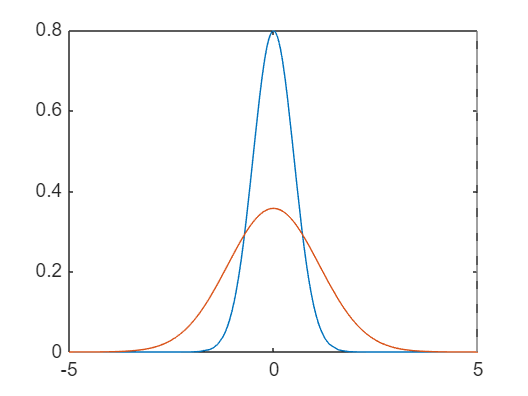

clear pi
psit2num = subs(psit2(x,t), {a, m, hbar, sym('pi')}, {1, 1, 1, pi});
figure;
fplot(subs(psit2num, t, 0), [-5 5])
hold on
fplot(subs(psit2num, t, 1), [-5 5])
fplot(subs(psit2num, t, 3), [-5 5])
hold off

 
%% d)
xave = simplify(int(psit2(x,t)*x,x,-inf,inf))

$$xave = 0$$

x2ave = simplify(int(psit2(x,t)*x^2,x,-inf,inf))

$$x2ave = \frac{\pi \,\left(4\,a^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}\right)}{4\,a\,m^{2}\,\pi }$$

pave = simplify(int(conj(psitime(x,t))*hbar/1i*diff(psitime(x,t),x),x,-inf,inf))

$$pave = 0$$

p2ave = simplify(int(conj(psitime(x,t))*(-hbar^2)*diff(psitime(x,t),x,2),x,-inf,inf))

$$p2ave = \frac{\pi \,a\,{\mathrm{hbar}}^{2}\,\sqrt{4\,a^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}{\pi \,\sqrt{m-2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}}$$

sigmax = simplify(sqrt(x2ave-xave^2))

$$sigmax = \frac{\sqrt{\pi }\,\sqrt{4\,a^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}{2\,\sqrt{a}\,m\,\sqrt{\pi }}$$

sigmap = simplify(sqrt(p2ave-pave^2))

$$sigmap = \frac{\sqrt{a}\,\mathrm{hbar}\,\sqrt{\pi }\,{\left(4\,a^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}\right)}^{1/4}\,\sqrt{\frac{1}{\sqrt{m-2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}}}}{\sqrt{\pi }}$$

 
%% e)
uncertainty = simplify(sigmax*sigmap)

$$uncertainty = \frac{\pi \,\mathrm{hbar}\,{\left(4\,a^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}\right)}^{3/4}\,\sqrt{\frac{1}{\sqrt{m-2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,a\,\mathrm{hbar}\,t\,\mathrm{i}}}}}{2\,m\,\pi }$$

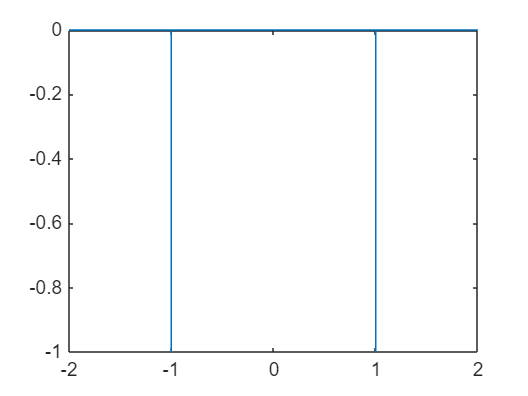

%% At t =0 it is greater than hbar/2 meaning it satisfies hesisernberg uncertainty principle
 
%% 2.27
clearvars;
clc;
m = sym('m','positive');
h = sym('h','positive');
a = sym('a','positive');
alpha = sym('alpha','positive');
x = sym('x','real');
E = sym('E','positive');
k = sqrt(2*m*E/h^2);
syms A B

%% a)
figure;
plot([-2 -1 -1 -1 1 1 1 2], [0 0 -1 0 0 -1 0 0])


%% b)
psi1(x) = B*(exp(k*x) + exp(-k*x));
psi2(x) = B*(exp(k*x) - exp(-k*x));
psi3(x) = A*exp(-k*x);
dpsi1(x) = diff(psi1(x), x);
dpsi2(x) = diff(psi2(x), x);
dpsi3(x) = diff(psi3(x), x);
A1 = solve(psi3(a) == psi1(a), A)

$$A1 = B+B\,{\mathrm{e}}^{\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}$$

A2 = solve(psi3(a) == psi2(a), A)

$$A2 = B\,{\mathrm{e}}^{\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}-B$$

eq1 = subs(dpsi3(a) - dpsi1(a) == -2*m*alpha/h^2*psi3(a), A, A1)

$$eq1 = \begin{array}{l} -B\,\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}}{h}-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}}{h}\right)-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}\,\sigma_{2}}{h}=-\frac{2\,\alpha \,m\,\sigma_{1}\,\sigma_{2}}{h^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}\\ \sigma_{2}=B+B\,{\mathrm{e}}^{\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}} \end{array}$$

eq2 = subs(dpsi3(a) - dpsi2(a) == -2*m*alpha/h^2*psi3(a), A, A2)

$$eq2 = \begin{array}{l} \frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}\,\sigma_{2}}{h}-B\,\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}}{h}+\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}}{h}\right)=\frac{2\,\alpha \,m\,\sigma_{1}\,\sigma_{2}}{h^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}\\ \sigma_{2}=B-B\,{\mathrm{e}}^{\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}} \end{array}$$

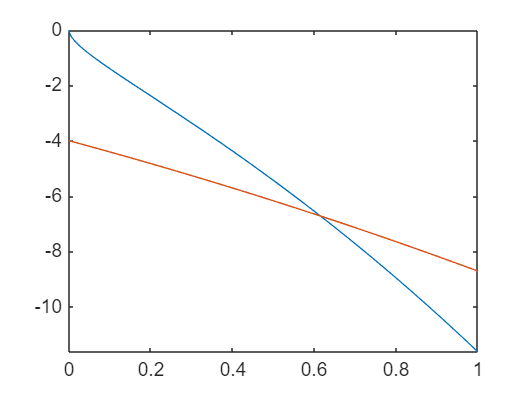

eq11 = subs(eq1, [m,h,alpha,a,B], [1,1,1,1,1]);
eq12 = subs(eq1, [m,h,alpha,a,B], [1,1,1/4,1,1]);
eq21 = subs(eq2, [m,h,alpha,a,B], [1,1,1,1,1]);
eq22 = subs(eq2, [m,h,alpha,a,B], [1,1,1/4,1,1]);

figure;
fplot(lhs(eq11), [0 1])
hold on
fplot(rhs(eq11), [0 1])
hold off

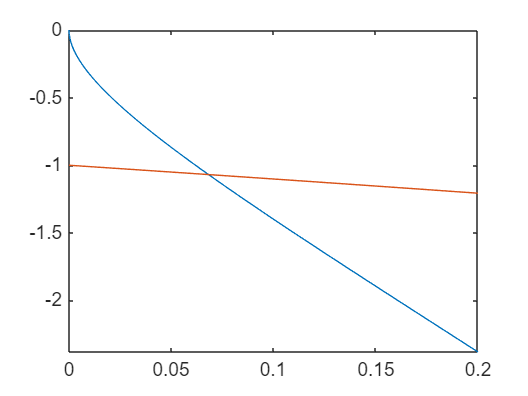


figure;
fplot(lhs(eq12), [0 0.2])
hold on
fplot(rhs(eq12), [0 0.2])
hold off

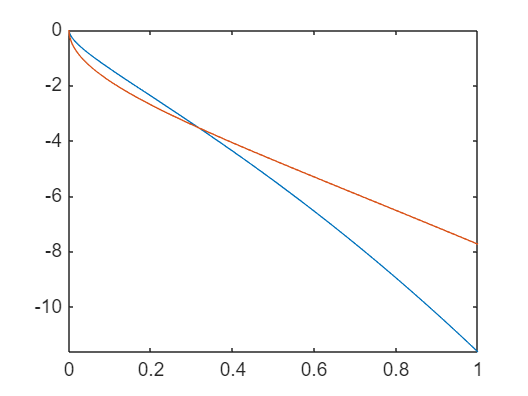


figure;
fplot(lhs(eq21), [0 1])
hold on
fplot(rhs(eq21), [0 1])
hold off

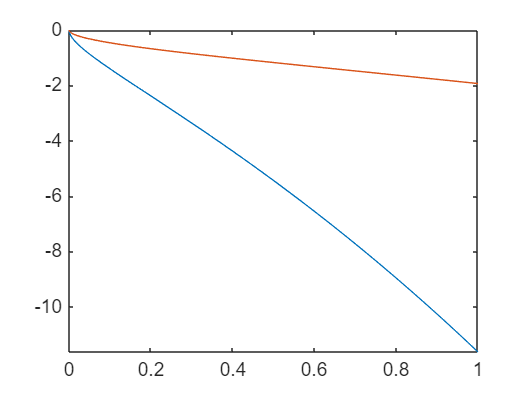


figure;
fplot(lhs(eq22), [0 1])
hold on
fplot(rhs(eq22), [0 1])
hold off

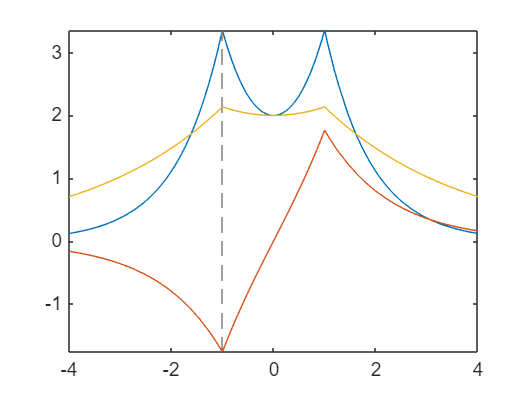


E1 = 0.615;
E2 = 0.317;
E3 = 0.068;

psi4(x) = piecewise(x < -a, A1*exp(k*x), x > a, A1*exp(-k*x), psi1(x));
psi5(x) = piecewise(x < -a, -A2*exp(k*x), x > a, A2*exp(-k*x), psi2(x));
figure;
fplot(subs(psi4(x), [m,h,a,B,E], [1,1,1,1,E1]), [-4 4])
hold on
fplot(subs(psi5(x), [m,h,a,B,E], [1,1,1,1,E2]), [-4 4])
fplot(subs(psi4(x), [m,h,a,B,E], [1,1,1,1,E3]), [-4 4])
hold off

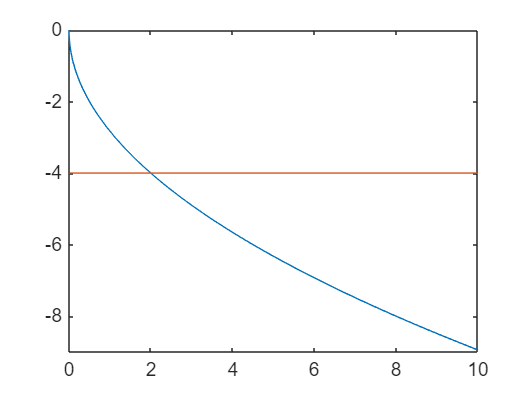


%% c)
eq31 = subs(eq1, [m,h,alpha,a,B], [1,1,1,0,1]);
eq32 = subs(eq2, [m,h,alpha,a,B], [1,1,1,0,1]);

figure;
fplot(lhs(eq31), [0 10])
hold on
fplot(rhs(eq31), [0 10])
hold off

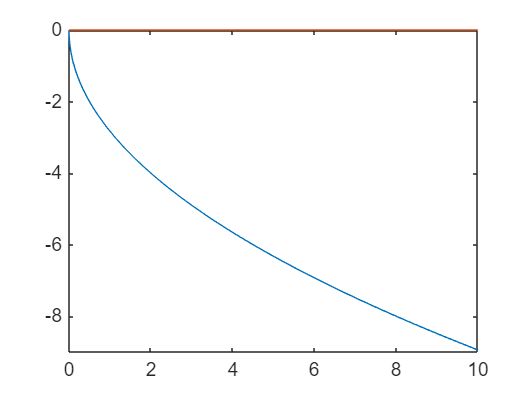


figure;
fplot(lhs(eq32), [0 10])
hold on
fplot(rhs(eq32), [0 10])
hold off


eq3 = exp(-2*k*a) == h^2*k/(m*alpha) - 1

$$eq3 = {\mathrm{e}}^{-\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}=\frac{\sqrt{2}\,\sqrt{\text{E}}\,h}{\alpha \,\sqrt{m}}-1$$

eq4 = exp(-2*k*a) == 1 - h^2*k/(m*alpha)

$$eq4 = {\mathrm{e}}^{-\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{h}}=1-\frac{\sqrt{2}\,\sqrt{\text{E}}\,h}{\alpha \,\sqrt{m}}$$

E5 = solve(0 == rhs(eq3), E)

$$E5 = \frac{\alpha^{2}\,m}{2\,h^{2}}$$

E6 = solve(0 == rhs(eq4), E)

$$E6 = \frac{\alpha^{2}\,m}{2\,h^{2}}$$

%%2.34)
clearvars;
clc;
syms x
m = sym('m', 'positive');
h = sym('h', 'positive');
E = sym('E', 'positive');
V = sym('V', 'positive');
k = sym('k', 'positive');
l = sym('l', 'positive');
A = sym('A', 'positive');
syms B F
 
%% a)
psil(x) = A*exp(1i*k*x) + B*exp(-1i*k*x);
dpsil(x) = diff(psil(x), x);
psir(x) = F*exp(-l*x);
dpsir(x) = diff(psir(x), x);
[Ba, Fa] = solve([psil(0) == psir(0), dpsil(0) == dpsir(0)], [B, F])

$$Ba = \frac{A\,\left(l+k\,\mathrm{i}\right)}{-l+k\,\mathrm{i}}$$

$$Fa = \frac{2\,A\,k\,\mathrm{i}}{-l+k\,\mathrm{i}}$$

Ra = simplify(conj(Ba)*Ba/A^2)

$$Ra = 1$$

 
%% b)
psir(x) = F*exp(1i*l*x);
dpsir(x) = diff(psir(x), x);
[Bb, Fb] = solve([psil(0) == psir(0), dpsil(0) == dpsir(0)], [B, F])

$$Bb = \frac{A\,\left(k-l\right)}{k+l}$$

$$Fb = \frac{2\,A\,k}{k+l}$$

Rb = simplify(conj(Bb)*Bb/A^2)

$$Rb = \frac{{\left(k-l\right)}^{2}}{{\left(k+l\right)}^{2}}$$

RbE = simplify(subs(Rb, [k l], [sqrt(2*m*E)/h, sqrt(2*m*(E-V))/h]))

$$RbE = -\frac{V-2\,\text{E}+2\,\sqrt{\text{E}}\,\sqrt{\text{E}-V}}{2\,\text{E}-V+2\,\sqrt{\text{E}}\,\sqrt{\text{E}-V}}$$

Rbtheo = (sqrt(E)-sqrt(E-V))^4/V^2

$$Rbtheo = \frac{{\left(\sqrt{\text{E}}-\sqrt{\text{E}-V}\right)}^{4}}{V^{2}}$$

checkR = simplify(RbE - Rbtheo)

$$checkR = 0$$

 
%% c)
Tb = simplify((l/k)*conj(Fb)*Fb/A^2)

$$Tb = \frac{4\,k\,l}{{\left(k+l\right)}^{2}}$$

TbE = simplify(subs(Tb, [k l], [sqrt(2*m*E)/h, sqrt(2*m*(E-V))/h]))   

$$TbE = \frac{4\,\sqrt{\text{E}}\,\sqrt{\text{E}-V}}{2\,\text{E}-V+2\,\sqrt{\text{E}}\,\sqrt{\text{E}-V}}$$

%% d)
RT = simplify(Rb + Tb)

$$RT = 1$$

Rsub = subs(RbE, [V m h], [1 1 1])

$$Rsub = -\frac{2\,\sqrt{\text{E}}\,\sqrt{\text{E}-1}-2\,\text{E}+1}{2\,\text{E}+2\,\sqrt{\text{E}}\,\sqrt{\text{E}-1}-1}$$

Tsub = subs(TbE, [V m h], [1 1 1])

$$Tsub = \frac{4\,\sqrt{\text{E}}\,\sqrt{\text{E}-1}}{2\,\text{E}+2\,\sqrt{\text{E}}\,\sqrt{\text{E}-1}-1}$$

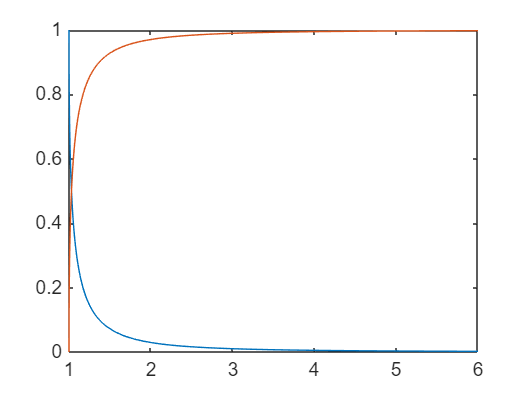

figure;
fplot(Rsub, [1 6])
hold on
fplot(Tsub, [1 6])
hold off